## EARTH 175 Final Project

## Nikhita Kalluri

## UCSB Winter 2024

# Abstract

This project addresses the impact of global warming by analyzing temperature trends over time on both land and ocean surfaces. Utilizing The Global Land and Ocean-Temperature Anomaly Time Series dataset, which examines anomalies in annual mean temperature from pre-industrial levels, this project aims to forecast future temperature changes. The dataset, sourced from NASA's GISS Surface Temperature Analysis and NOAA National Climatic Data Center, covers the period from 1880 to 2016, although the data I will use in this project covers from 1905 to 2016, occurring after the pre-industrial period to maintain the uniformity of the data, essential for tests of normality. The analysis incorporates the assessment of the time series transformations, such as Box-Cox and log transformations, and incorporates differencing to achieve stationarity of data. Multiple SARIMA models are fitted for forecasting, with model selection guided by the Akaike Information Criterion (AICc). The chosen model was tested for normality through the process of diagnostic checking. The chosen model, ARIMA(1, 1, 3), exhibits invertibility and successfully passes normality tests, qualifying it for forecasting. 

It's important to acknowledge that the complexity of the data, influenced by factors like the inherent variability of the climate system, natural disasters, volcanic eruptions, and unpredictable shifts in human contributions to emissions due to technological advances or events such as the COVID-19 pandemic, introduces nuances in the data. Consequently, deviations from the general pattern may occur. As a result, the final model may slightly deviate from the actual observations of future predictions, although the confidence intervals give a possible range. The chosen final model was: 


$$$Y_t - Y_{t-1} = Z_t - 0.0452*Z_{t-1} + 0.0414*Z_{t-2} + 0.0104*Z_{t-3}$$$


# Introduction

In the face of global warming it is important to understand temperature trends over time with both land and ocean surfaces. This analysis of trends can allow us to forecast average future temperature changes and understand how elements such as greenhouse gases, insolation, and ocean currents can affect temperature. 

The specific dataset the will be used in the course of this project is The Global Land and Ocean-Temperature Anamoly Time Series. This examines anomalies (measured in degrees Celsius) in annual mean temperature from the baseline temperature (determined from from pre-industrial global mean temperatures). Based on this information, future changes can be forecasted and determined, important to understanding the scale of global warming and future predictions. 

The primary objective of this project is to forecast future global temperature increases concerning the mean baseline temperature, utilizing current data spanning from 1880 to 2016. This data, accessible on datahub.io, is sourced from two entities:

- GISTEMP, originating from NASA's (GISS) Surface Temperature Analysis, Global Land-Ocean Temperature Index.

- NOAA National Climatic Data Center (NCDC).

The dataset includes two variables: 'Year,' an integer ranging from 1880 to 2016, and 'Mean,' an integer ranging from -0.5 (indicating a cooling of 0.5 degrees below the pre-industrial global mean temperature) to 1 (indicating a heating of 1 degree Celsius from pre-industrial global mean temperatures).

To forecast future global warming based on past temperature anomalies, the process begins by dividing the data into training and testing sets. After analyzing the training set, the subsequent step involves making the series stationary by transforming the data and eliminating trend and seasonality components. Once the series is stationary, models that align well based on Autocorrelation Functions and Partial Autocorrelation Functions are identified, and the Akaike Information Criterion is employed to determine the most satisfactory model once the process of diagnostic checking shows that the model is satisfactory. Once the model is selected, it can be utilized to forecast future temperature anomaly predictions.

clear;
plots_folder = '/Users/nkalluri/Desktop/EARTH 175 Final/plots/';


f = finalFunctions();

# Read in Data

To begin, the data must be read in as a CSV file. This dataset currently has two mean observations per year. To address this, we can group the data by year and generate a new dataframe with a single mean observation per year. Additionally, the data before the 1900s seems to be stagnant, not following the linear trend that the rest of the data follows. To more accurately forecast the data, I will be working with data only after 1905. It is also important to note that the Means will be upshifted by 0.44805, which is the global mean temperature corresponding to 1909, where the most cooling occurred. This is because later transformations such as the Box-Cox and log transformations do not accept negative values.

% read in data from csv file
data = readtable('/Users/nkalluri/Desktop/EARTH 175 Final/data/global_temp.csv');

new_Dat = data(:, {'Year', 'Mean'});

% find mean of the two samples collected for each month and group them together 
% so that there is one Mean observation per year
grouped_mean = grpstats(new_Dat.Mean, new_Dat.Year, 'mean');

% Create a new table with Year variable and the computed mean
new_dat = table(unique(new_Dat.Year), grouped_mean, 'VariableNames', {'Year', 'Mean'});

% since there are negative mean values which are not suitable for later Box Cox 
% transformations shift mean up by the lowest value which occurred in 1909 -> 0.44805
new_dat.Mean = new_dat.Mean + 0.44805;

% select the specific rows that  match the normal trend to preserve
% normality of data for future tests
new_dat = new_dat(26:137, :);
disp(new_dat);% convert to time series object and plot the time series

    Year       Mean   
    ____    __________

    1905        0.1615
    1906       0.22435
    1907       0.06275
    1908       0.01325
    1909    5.5511e-17
    1910        0.0486
    1911       0.01145
    1912       0.10865
    1913       0.11995
    1914        0.2983
    1915        0.3584
    1916       0.13155
    1917       0.09075
    1918       0.21385
    1919        0.2353
    1920        0.2078
    1921        0.2688
    1922       0.19285
    1923       0.22025
    1924       0.18375
    1925         0.269
    1926        0.3647
    1927       0.26575
    1928       0.25435
    1929        0.1188
    1930        0.3229
    1931       0.36875
    1932       0.30465
    1933        0.1811
    1934        0.3273
    1935       0.27845
    1936       0.31635
    1937        0.4252
    1938       0.41865
    1939        0.4261
    1940        0.5354
    1941       0.60605
    1942       0.56995
    1943   

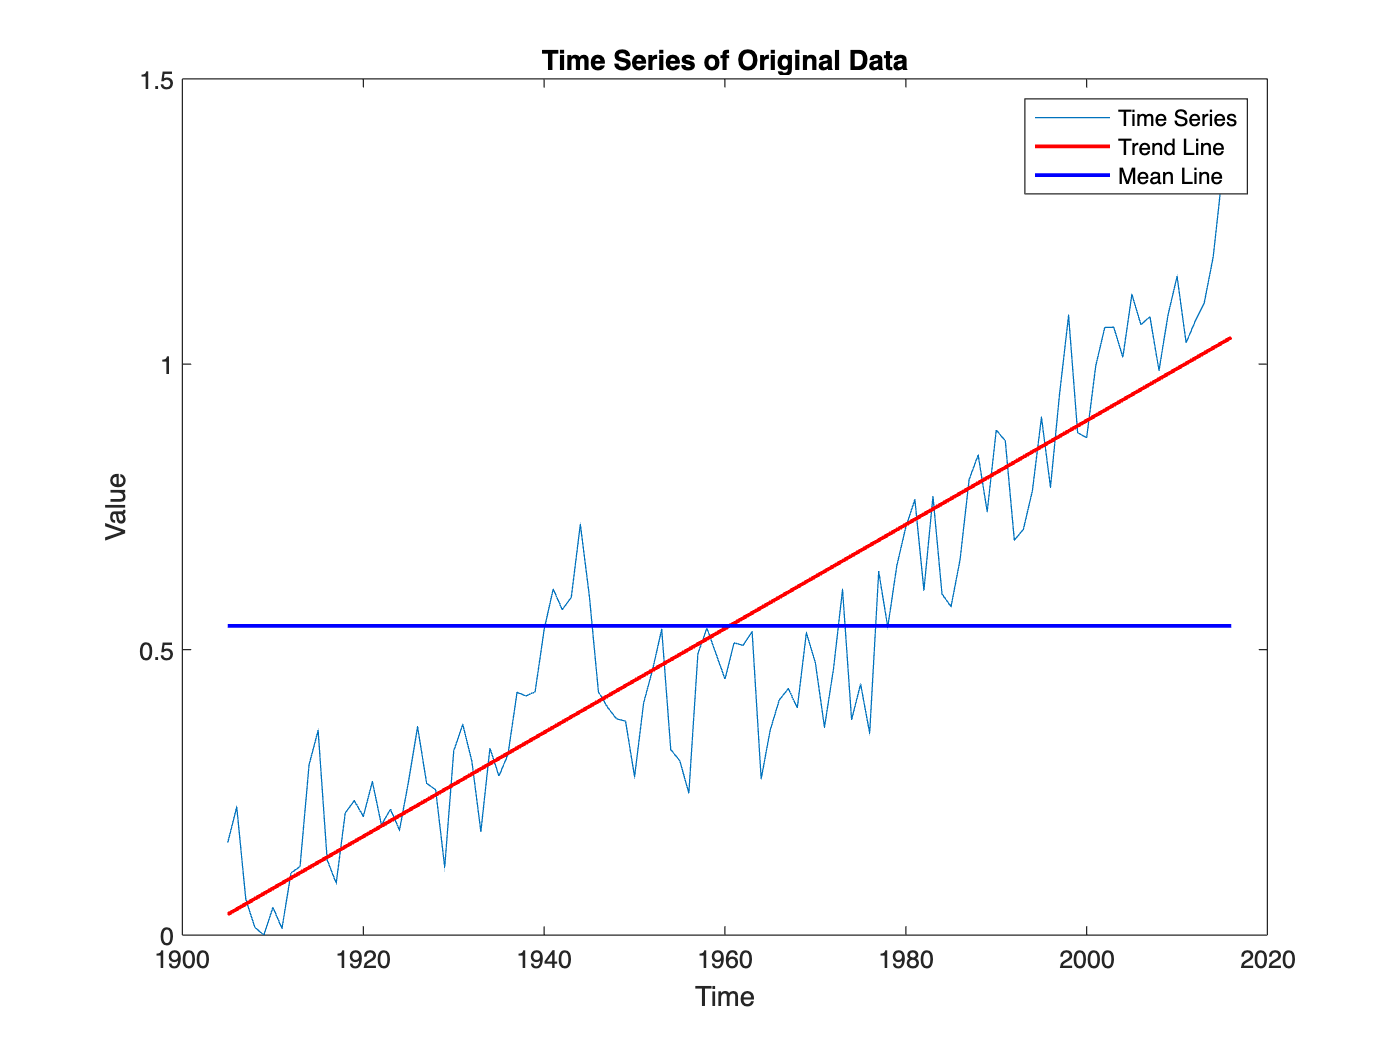

climate = timeseries(new_dat.Mean, new_dat.Year);
f.plot_time_series(climate);
title('Time Series of Original Data');
figure(1);
    hold on

Visualizing the time series data as a plot, an upward trend is apparent. Additionally, there is variability, characterized by cyclic variations in the graph's curvature suggesting potential seasonality. Additionally, the variance appears to exhibit only a marginal increase over the range of years. It is important to note the upward peak around the 40th observation which might affect the linear trend.

# Partition Data into Train and Test Sets

To begin with, we want to create a training and testing data set for the model to be trained on and tested on for performance. The training set will be used to train our models on, while the testing set will serve as new data for our models to be tested on.

I decided to use a 75/30 split, with 75% of the data used for training and 25% of the data used for testing. This will increase the model performance, while still having a decent amount of data left to test on.

% Calculate the index to split the data
split_index = floor(length(climate.Data) * 0.75);

% Create training and testing sets
train = getsamples(climate, 1:split_index);
test = getsamples(climate, split_index+1:length(climate.Data));


# Data Exploration

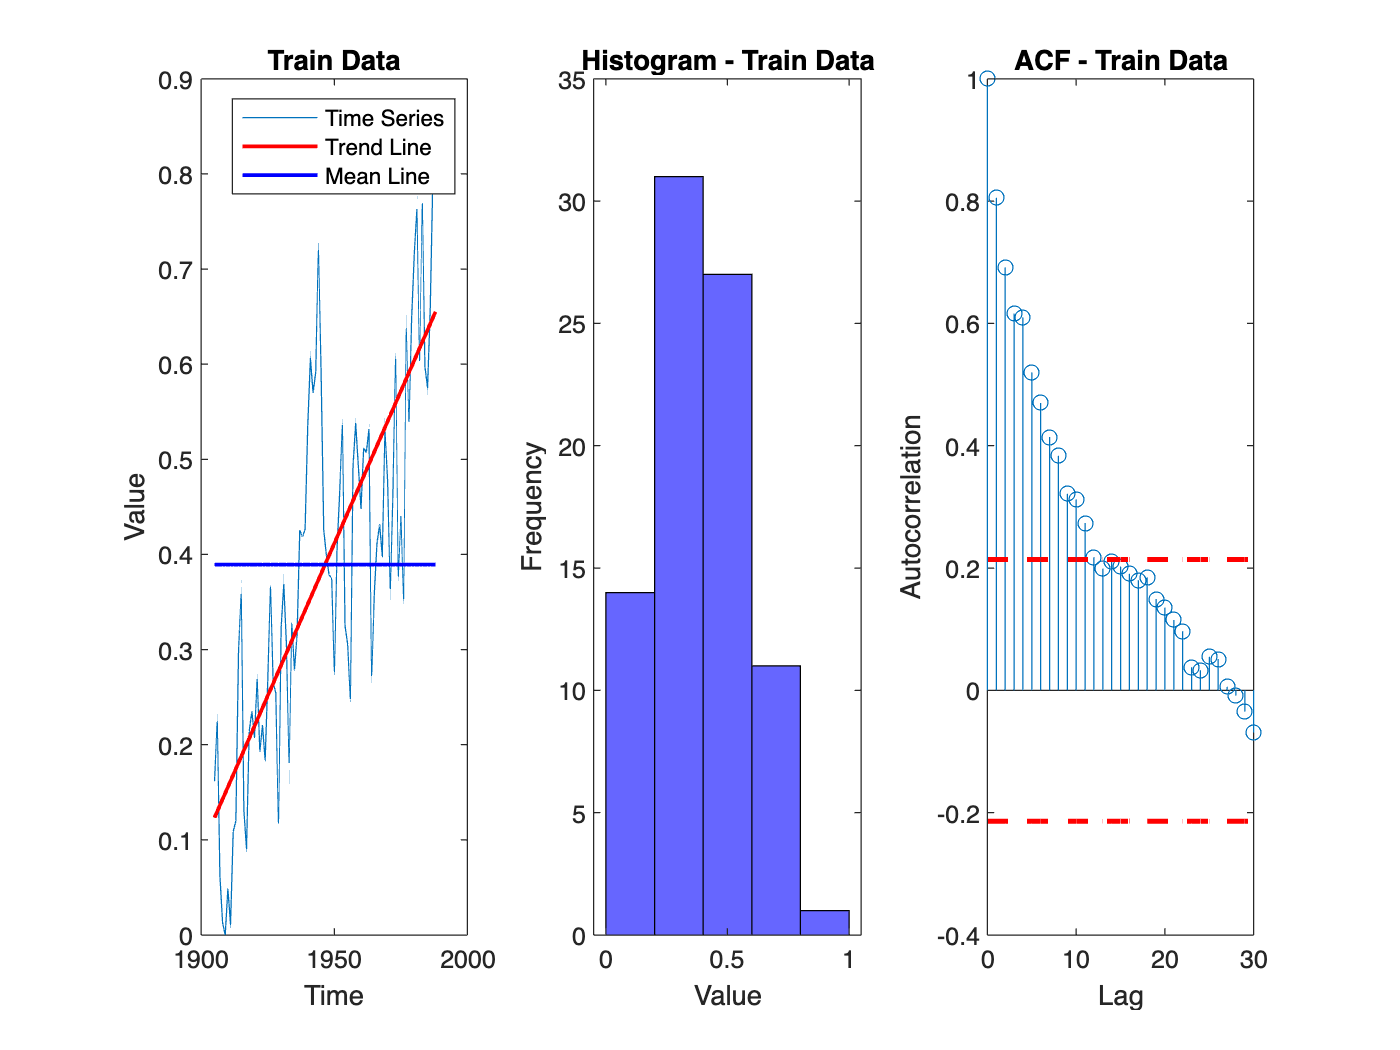

% Plot the time series with mean and trend
subplot(1, 3, 1);
f.plot_time_series(train)
title('Train Data');

subplot(1, 3, 2);
f.plot_histogram(train);
title('Histogram - Train Data');

subplot(1, 3, 3);
f.plot_acf(train.data);
title('ACF - Train Data');

figure(2);


Based on the time series graph, there is a clear linear upward trend as indicated by the trend line. Variance seems relatively constant only slightly increasing through the progression of years. A notable feature of the graph is the upward curve followed by a downward cooling period in the middle of the graph which might be shifting the trend line upward. 

From the histogram, there is a very slight skew of mean observations to the right, suggesting that the data is not entirely Gaussian and may require transformation.

The autocorrelation function exhibits a slow downward trend suggesting that the series is most likely nonstationary. In addition, the ACF seems to be slightly periodic as seen by cyclical curvature, suggesting that there might be a seasonal component that needs to be differenced. To make the series stationary, we can explore some transformations. 

# Transformations

% The first transformation is Box-Cox transformation.
[train_bc, lambdas] = boxcox(train.Data); 

The optimal lambda value if we choose the box-cox transformation is 0.4963.

% Next, we can apply a log transformation.
train_log = log(train.Data);

In order to see which model fits the best, I plotted the original data, box-cox transformed data, and log transformed data along with their corresponding histograms. 

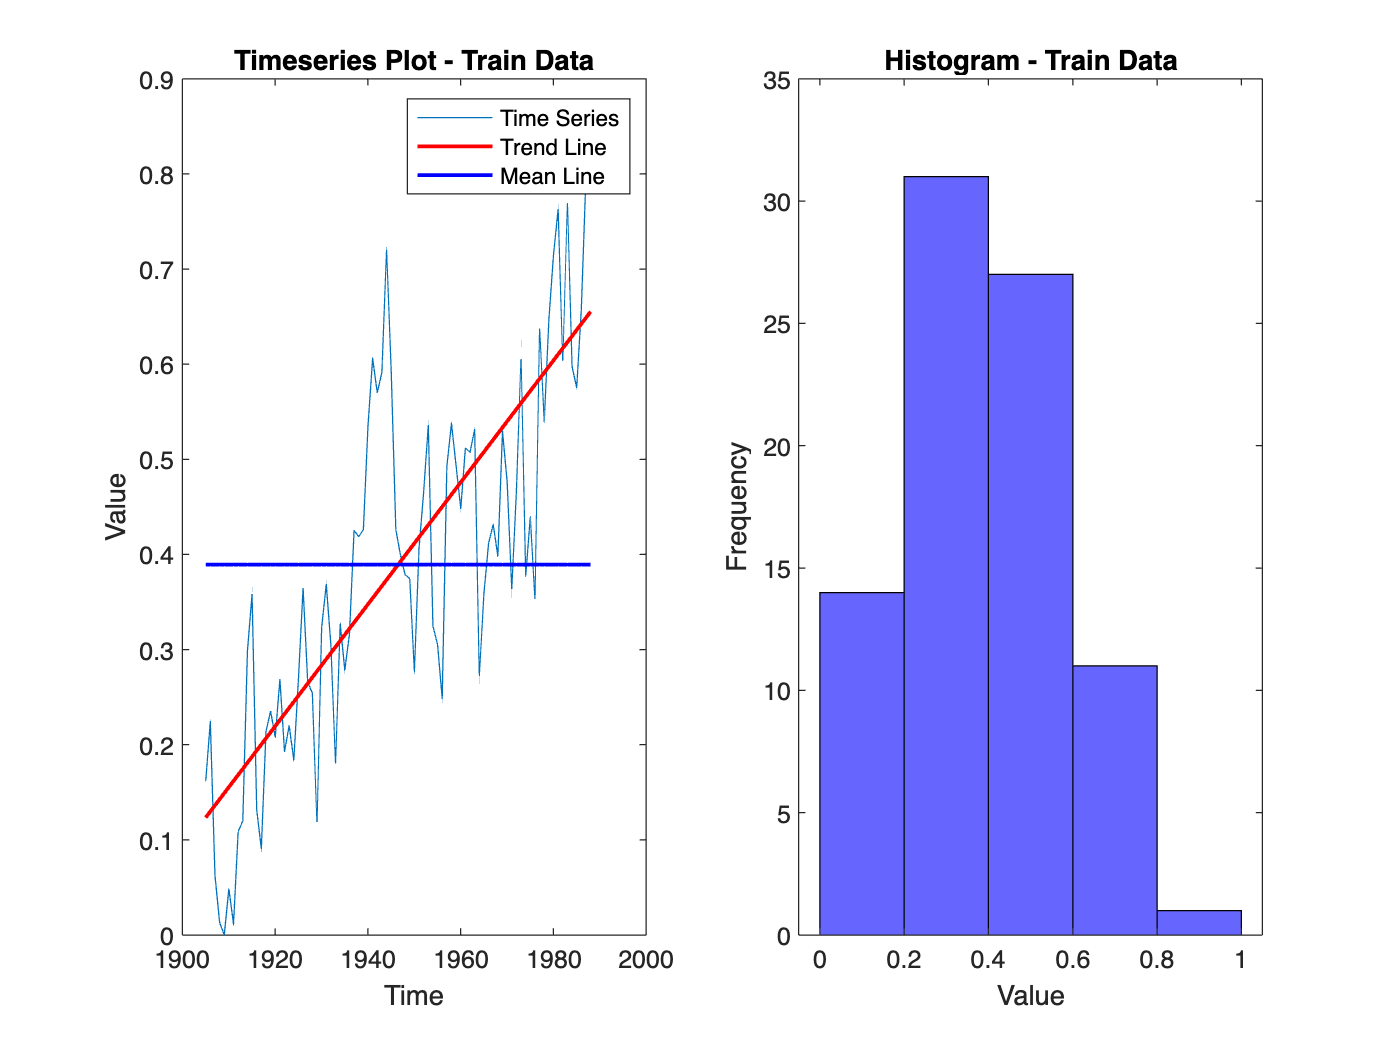

% Plots for train data
subplot(1, 2, 1);
f.plot_time_series(train);
title('Timeseries Plot - Train Data');

subplot(1, 2, 2);
f.plot_histogram(train);
title('Histogram - Train Data');

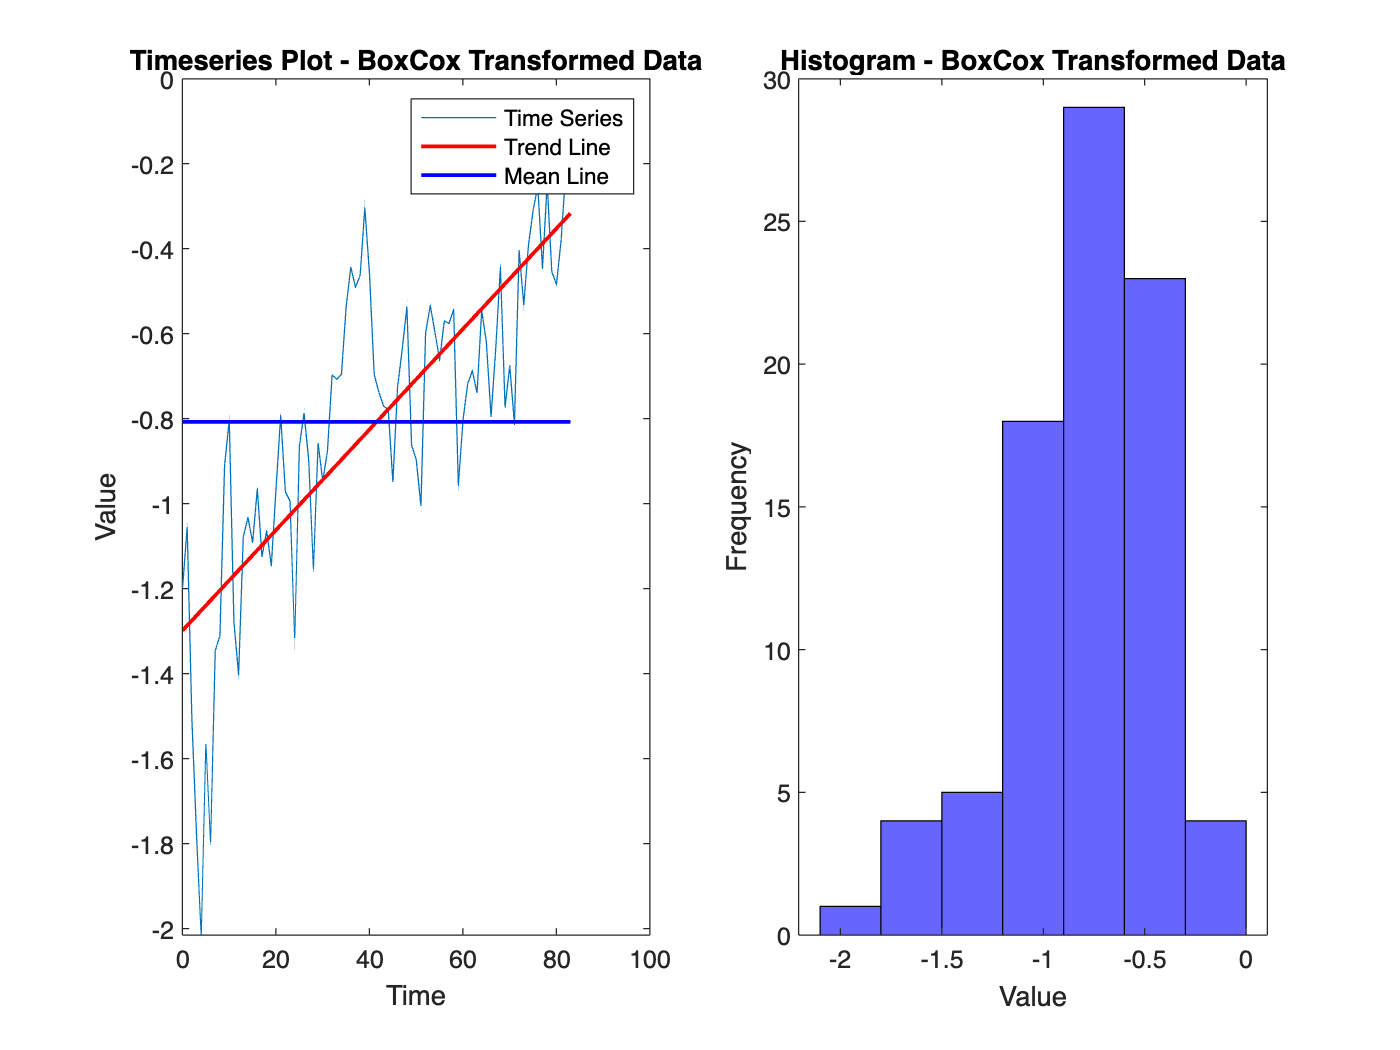

figure(3);

% Plots for box-cox tranformed data
subplot(1, 2, 1);
f.plot_time_series(timeseries(train_bc));
title('Timeseries Plot - BoxCox Transformed Data');

subplot(1, 2, 2);
f.plot_histogram(timeseries(train_bc));
title('Histogram - BoxCox Transformed Data');

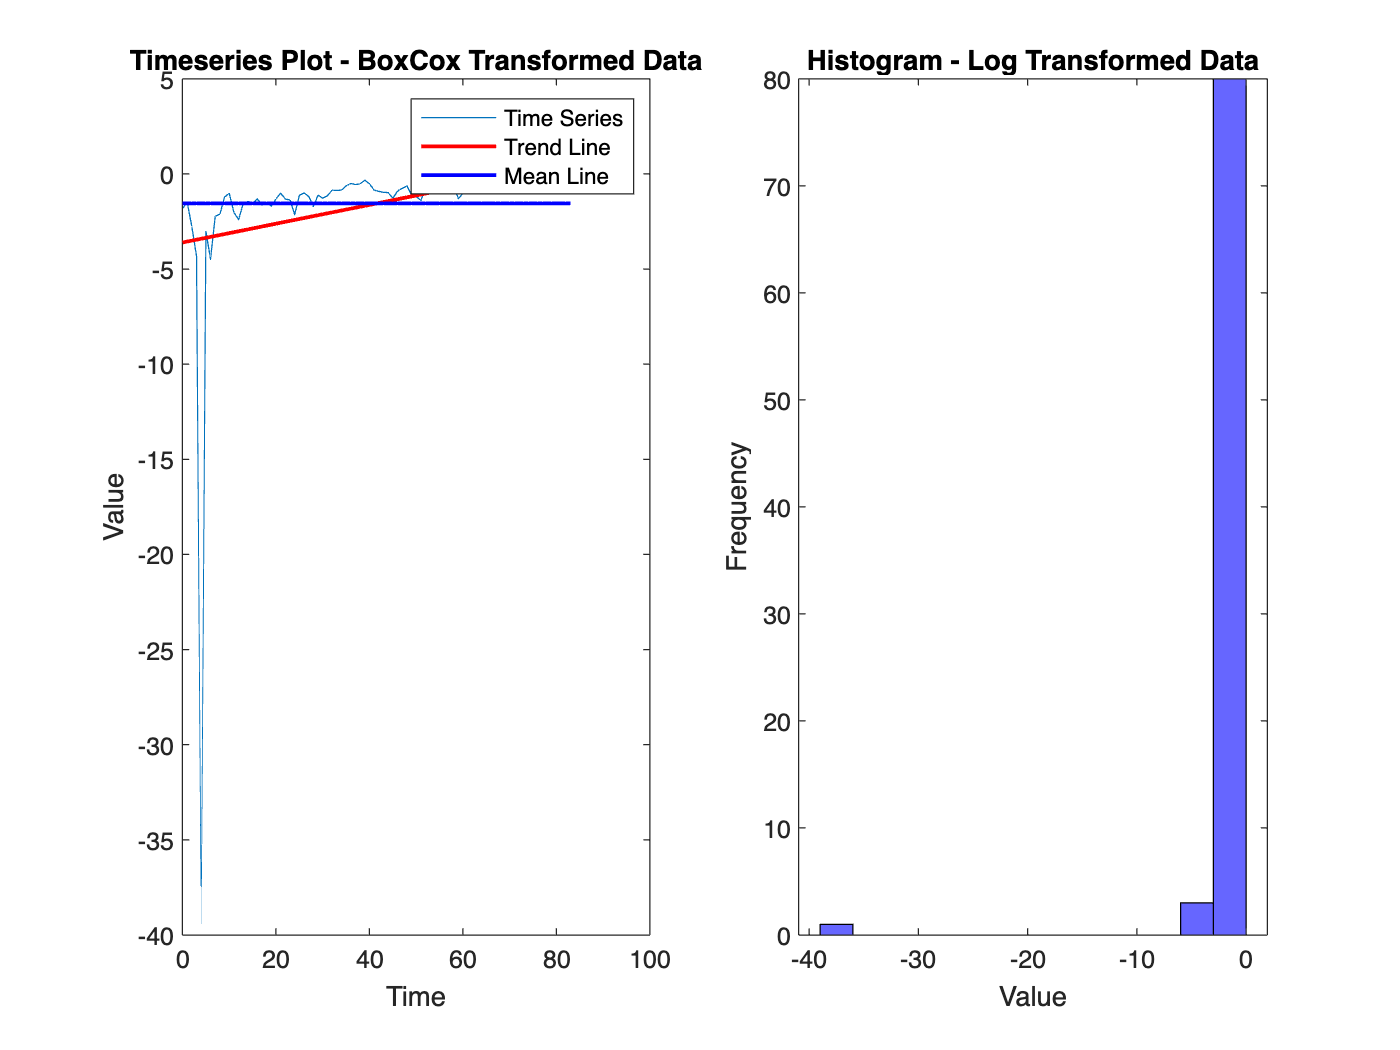

figure(4);



% Plots for log tranformed data
subplot(1, 2, 1);
f.plot_time_series(timeseries(train_log));
title('Timeseries Plot - BoxCox Transformed Data');

subplot(1, 2, 2);
f.plot_histogram(timeseries(train_log));
title('Histogram - Log Transformed Data');

figure(5);


From the plots, the original data seems to have the least variability with the slowest change in y-values throughout the course of time while the log-transformed data has the highest variance.

Based on the histogram, the original training data also has the most normal distribution with most of the values concentrated towards the center and the distribution appearing to be symmetric. The log transformed data has the least normal distribution with a skew to the left and values concentrated to the right. In order to make sure this is the case, we can check the variance of the original data, box-cox transformed data, and log transformed data.

var_train = var(train);
var_train_bc = var(train_bc);
var_train_log = var(train_log);

disp('Variance of Transformed Data')

Variance of Transformed Data


disp(['var_train: ', num2str(var_train)]);

var_train: 0.037786


disp(['var_train_bc: ', num2str(var_train_bc)]);

var_train_bc: 0.13395


disp(['var_train_log: ', num2str(var_train_log)]);

var_train_log: 16.2754


The variance aligns with the observations in the graphs. The untransformed training set has the lowest variance of  0.0378, followed by the Box-Cox transformed data with a variance of   0.1339, with the log-transformed data exhibiting the highest variance of 16.2754. This suggests that using the original data is appropriate, and we can proceed with the differencing process.

Since the variance for the original, untransformed data is the lowest, we can choose to work with this data. In this data, there is a distinct upward trend and pronounced seasonality as seen through variations in data. Based on this, we can begin differencing  the training set. This involves experimenting with both a seasonal difference at lag 12 to eliminate seasonality and a difference at lag 1 to address the linear trend.

However, it is important to note that there is a slight shift from linearity in the trend due to an upward shift in data located around 1944 and a downward shift associated with the cooling period around 1946.

This might potentially impact the accuracy of forecasting with a SARIMA model.

# Analyzing ACF and PACF With Differencing

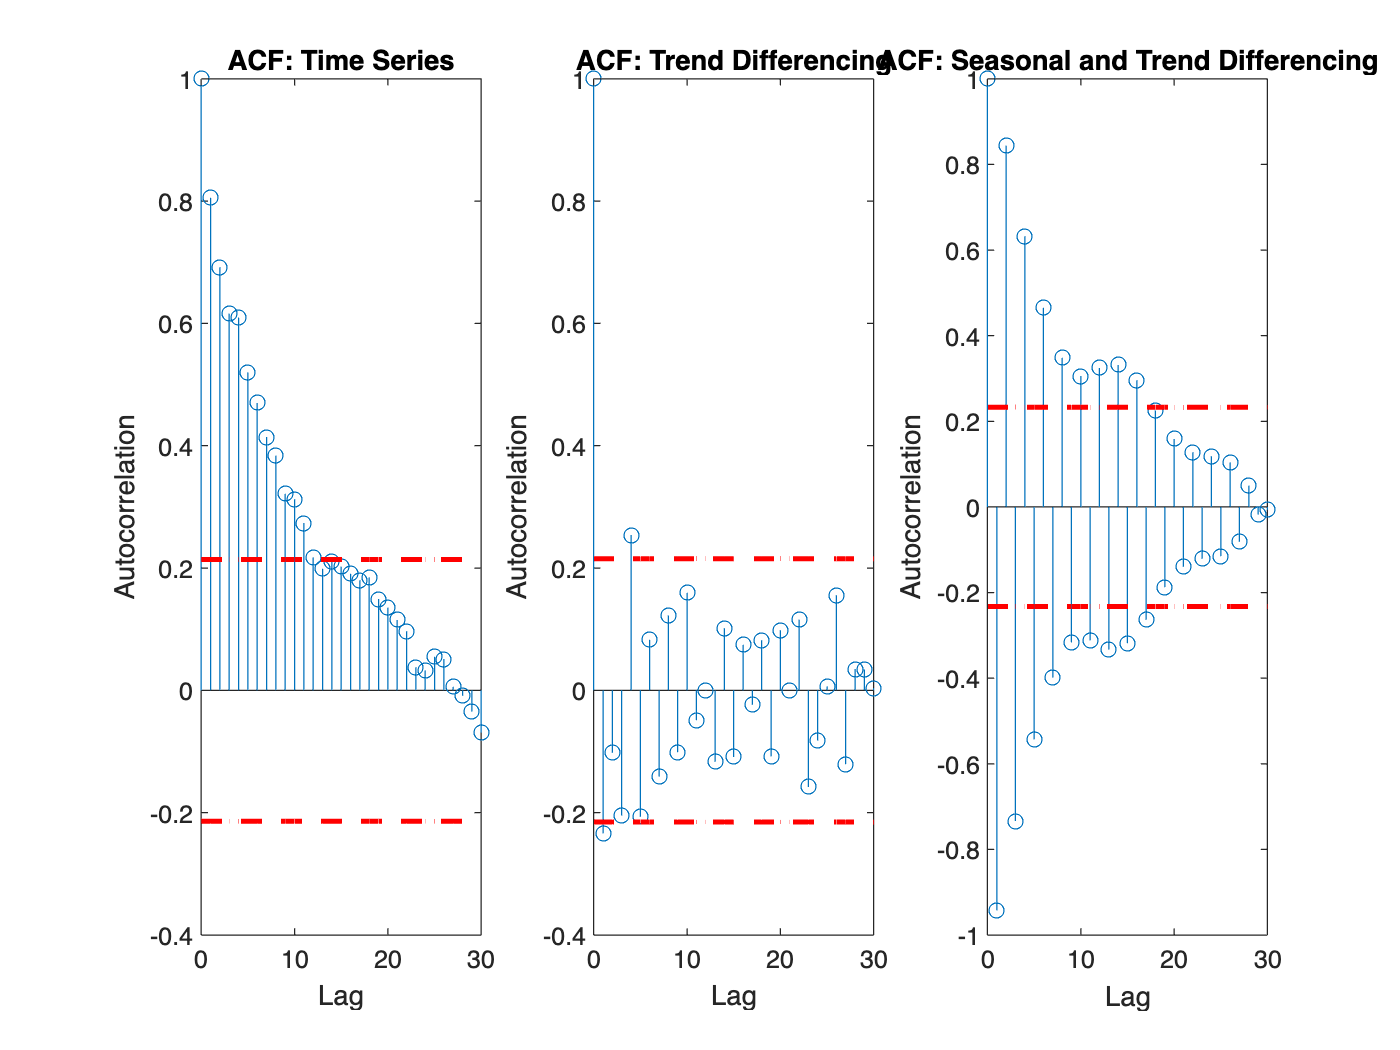



% Original Train Data
subplot(1, 3, 1);
f.plot_acf(train.data);
title('ACF: Time Series');

% First difference at only lag 1 to remove the trend since there is a clear upward trend
train_diff1 = diff(train.data, 1);

% Data Differenced at 1 for Trend
subplot(1, 3, 2);
f.plot_acf(train_diff1);
title('ACF: Trend Differencing');

% Then difference at both lag 1 and lag 12 to remove both the trend and
% seasonality
train_diff_s = diff(train_diff1, 12);

% Data Differenced at 1 and 12 for Trend and Seasonality
subplot(1, 3, 3);
f.plot_acf(train_diff_s);
title('ACF: Seasonal and Trend Differencing');

Based on the ACF plots above, the ACF of the original time series displays variance and a downward pattern indicating a trend. It also exhibits a gradual decrease, suggesting nonstationarity.

The trended time series eliminates the trend and looks relatively stationary although there is a gradual decrease in lags which may imply nonstationarity. Testing for seasonality by differencing at lag 12 however shows an increase in seasonality which shows nonstationarity.

disp('Variance of Differenced Data')

Variance of Differenced Data


disp(['var(train): ', num2str(var(train))]);

var(train): 0.037786


disp(['var(train_diff1): ', num2str(var(train_diff1))]);

var(train_diff1): 0.011683


disp(['var(train_diff_s): ', num2str(var(train_diff_s))]);

var(train_diff_s): 54607.0092


Checking the variance yields the same results. Differencing for trend decreases the variance from 0.0378 to 0.0117, but differencing again for seasonality increases the variance significantly to 5.4607e+04. We can choose to go with the de-trended model.

# Exploring the Chosen Data

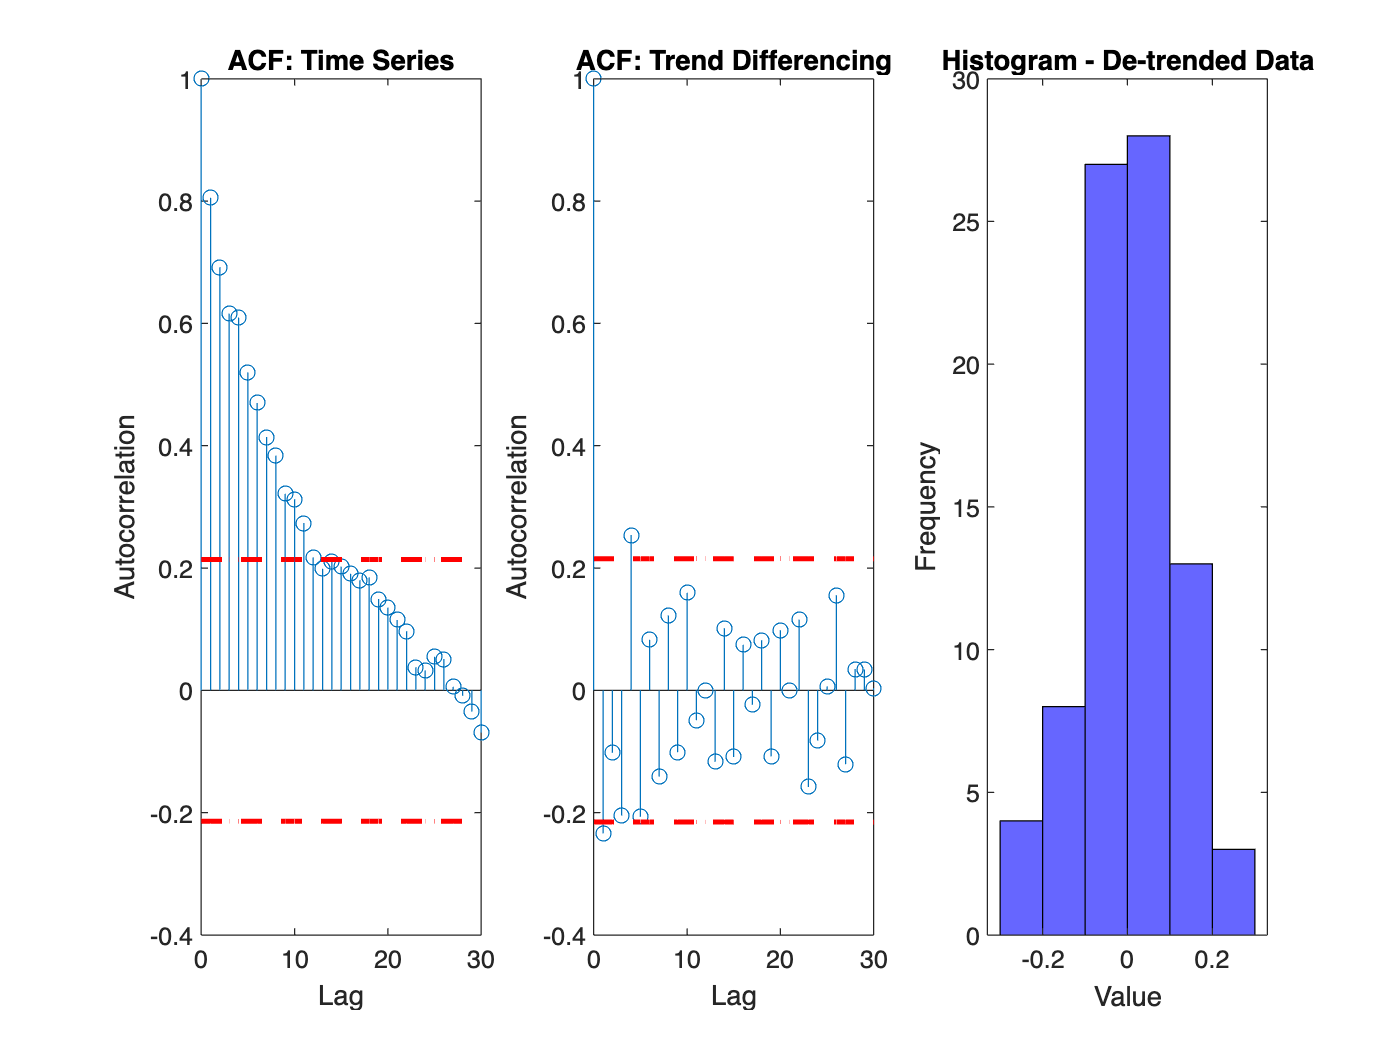

% Plotting the de-trended data
plot(train_diff1);
title('De-trended Data');
ylabel('X[t]');
% Plot the histogram
f.plot_histogram(timeseries(train_diff1))
title('Histogram - De-trended Data')

figure(8);

From the above plots, the differenced data does seem to be random suggesting stationarity and the histogram is normally distributed. Thus, we can choose the series that is differenced at 1.

# Model Selection

Now, we are ready to begin the process of model selection.

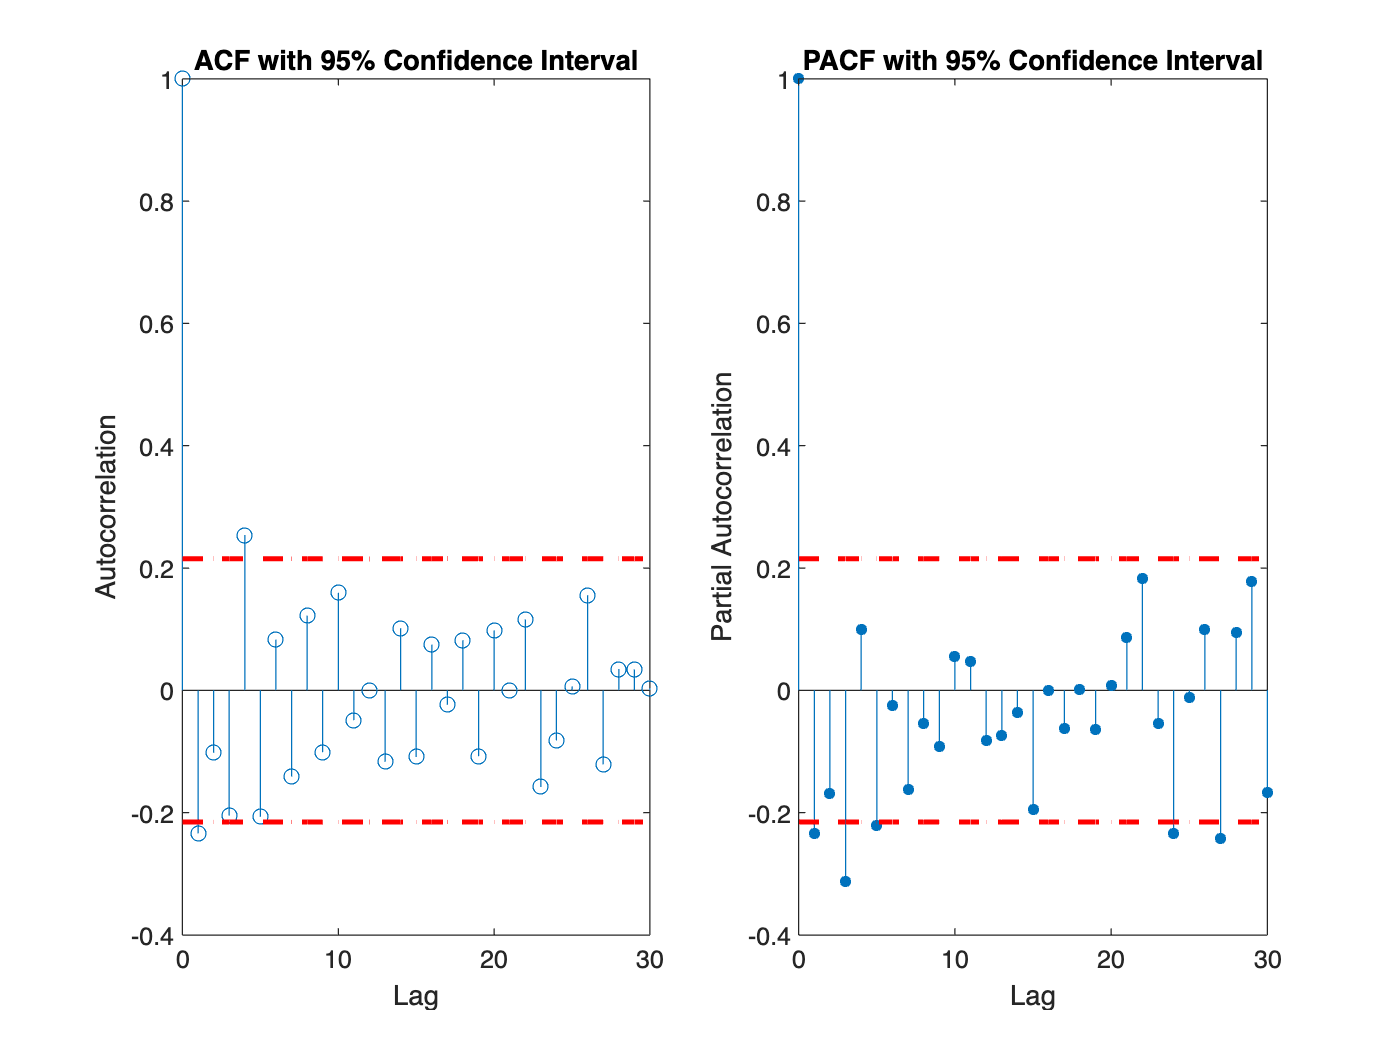

% Plot both the ACF and PACF to determine the model paramters.
figure();
subplot(1, 2, 1);
f.plot_acf(train_diff1);

subplot(1, 2, 2);
f.plot_pacf(train_diff1);

From the ACF above, there are 2 MA components outside the confidence interval including lags of either 2 or 3. Since there is no multiple of 12 with a significant lag, there is no seasonal component so Q=0.  As a result we can test models with q = 2 or 3, and Q= 0. 

Looking at the PACF which corresponds to the AR component, it seems that either at lag 1, 3, or 5, the corresponding ACF values go outside the confidence interval. Additionally, we differenced 1 time for trend and 0 times for seasonality so choose d = 1 and D = 0.

After fitting all the models based on the above criteria, fit all the models to a .MAT file based on the above criteria and write the AIC values to a text file to determine which moel performs best.

% Fit all the models base on the above criteria.
% Open file for writing
fileID = fopen('/Users/nkalluri/Desktop/EARTH 175 Final/output/aic_values.txt', 'w');

% Fit SARIMA models and write AIC values to file
q_values = [2, 3];
p_values = [1, 3, 5];
d = 1;

var = 1;
models = cell(length(p_values) * length(q_values), 1);

% Use a for loop to fit all the p, q, and d values for the models
for p = p_values
    for q = q_values
        [EstMdl, AIC] = f.fit_sarima_model(train_diff1, q, p, d);
        models{var} = EstMdl;
        
        % Write AIC and invertibility info to file
        fprintf(fileID, 'Model %d with q=%d, p=%d: AIC = %f\n', var, q, p, AIC);

        % Extract  MA coefficients from  estimated SARIMA model
        MA_cell = EstMdl.MA;
        MA_coefficients = cell2mat(MA_cell);
        
        % Check invertibility by inspecting the MA roots 
        is_invertible = all(abs(roots(MA_coefficients)) > 1);
        
        if is_invertible
            fprintf(fileID, 'Model invertiblity: invertible\n');
        else
            fprintf(fileID, 'Model invertiblity: not invertible\n');
        end
        var = var + 1;
    end
end

 
    ARIMA(2,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00012919     0.00057645       0.22411         0.82267
    AR{1}         -0.31997       0.081918        -3.906      9.3821e-05
    AR{2}         -0.17783        0.12106        -1.469         0.14184
    MA{1}               -1       0.080004       -12.499      7.5244e-36
    Variance      0.010589       0.002272        4.6608      3.1495e-06

AIC of the fitted model: -131.9321


 
    ARIMA(3,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00011434     0.00047063       0.24295         0.80805
    AR{1}         -0.37039       0.071273       -5.1968      2.0277e-07
    AR{2}         -0.28761        0.11016        -2.611       0.0090289
    AR{3}          -0.3339         0.1072       -3.1148       0.0018409
    MA{1}               -1       0.058179       -17.188      3.2489e-66
    Variance     0.0095507      0.0020466        4.6667      3.0604e-06

AIC of the fitted model: -138.5004
 
    ARIMA(2,3,1) Model (Gaussian Distribution):
 
                  Value     

 
    ARIMA(3,5,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0038319      0.0025939       -1.4773          0.1396
    AR{1}          -1.6431        0.10353       -15.871      1.0098e-56
    AR{2}           -1.433        0.15403       -9.3037      1.3564e-20
    AR{3}         -0.73523       0.088935       -8.2671      1.3726e-16
    MA{1}               -1        0.04937       -20.255      3.2087e-91
    Variance       0.11884       0.022417        5.3012      1.1507e-07

AIC of the fitted model: 70.7526




fclose(fileID);

% Save models to a MAT file
save('/Users/nkalluri/Desktop/EARTH 175 Final/output/sarima_models.mat', 'models');

Based on the AIC values in outputted file all models are invertible so we can look at the AIC. Model 2 with q=3, p=1 had the lowest AIC of -138.500357 followed by Model 1 with q=2, p=1 which had AIC = -131.932127. These will be the models we can choose for normality testing. 

We can now proceed to diagnostic checking for these models.

# Diagnostic Checking

We can check both the histogram of resiuals to make sure that it is normal as well as the plot of residuals to ensure that there is no trend. Additionally the Q-Q plot can tell us if it is normal based if the observations follow a straight line. 

First, we begin by working with Model 1. 

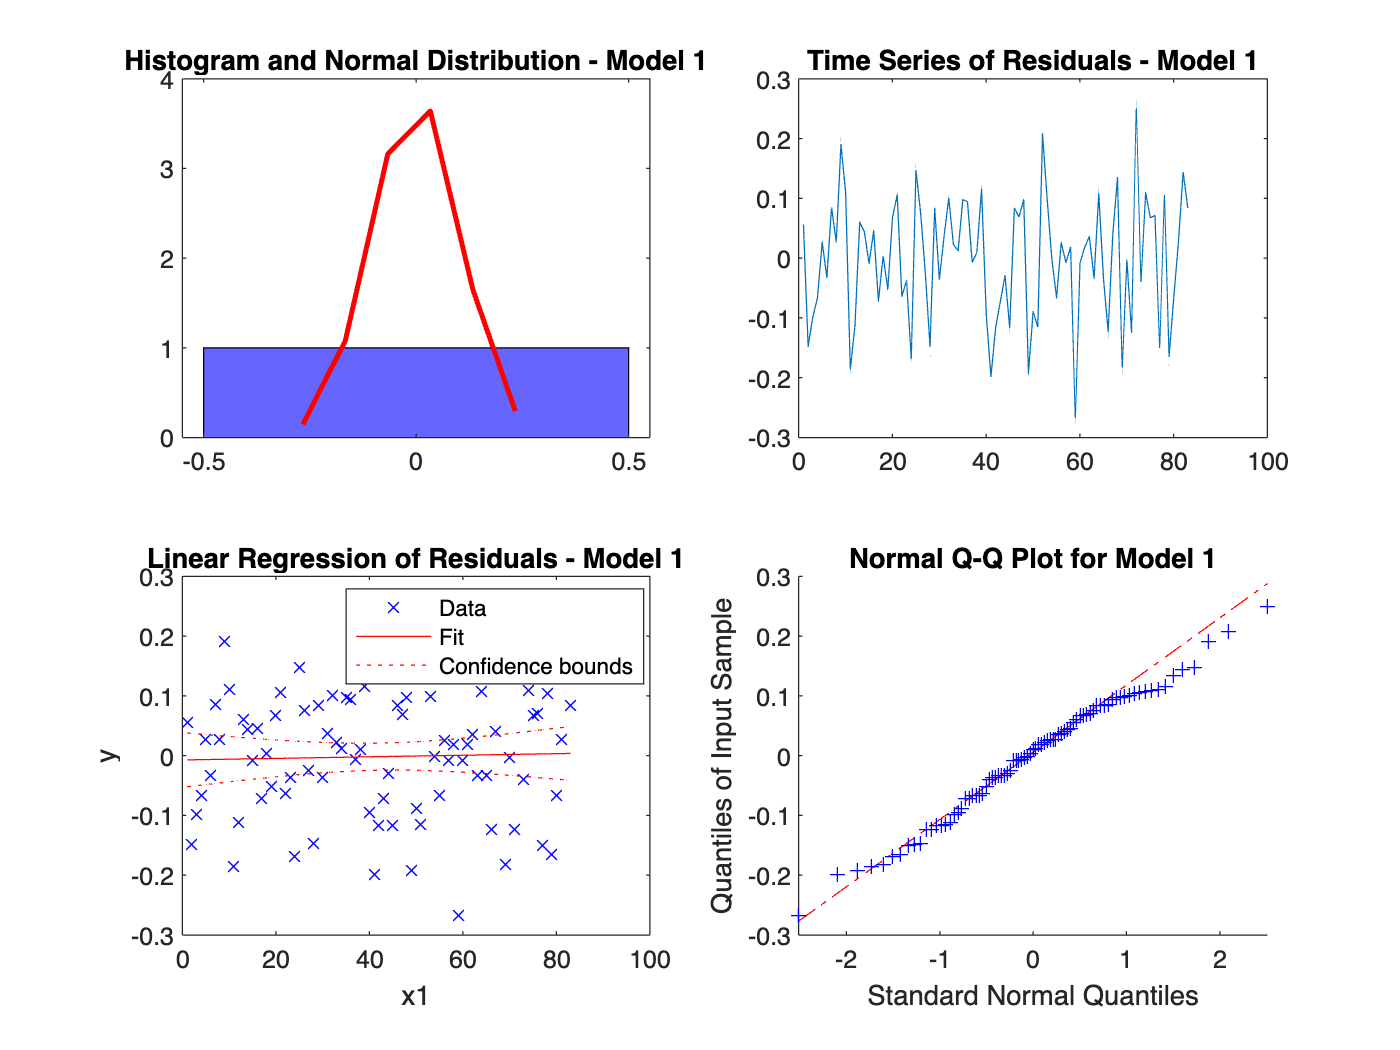

Model_1 = models{1};

% Calculate residuals
res = infer(Model_1, train_diff1);

% Histogram of residuals
figure();
subplot(2, 2, 1);
histogram(res, 'Normalization', 'pdf', 'BinMethod', 'integers', 'FaceColor', 'blue');
hold on;
m = mean(res);
std_dev = std(res);
x = min(res):0.1:max(res);
y = normpdf(x, m, std_dev);
plot(x, y, 'r', 'LineWidth', 2);
title('Histogram and Normal Distribution - Model 1');

% Plot time series of residuals
subplot(2, 2, 2);
plot(res);
title('Time Series of Residuals - Model 1');

% Linear regression of residuals
subplot(2, 2, 3);
fitt = fitlm((1:length(res))', res);
plot(fitt);
title('Linear Regression of Residuals - Model 1');

% QQ plot of residuals
subplot(2, 2, 4);
qqplot(res);
title('Normal Q-Q Plot for Model 1');

From the above plots, the histogram and Q-Q plot display normality. However,  the plot of residuals shows that the trend line slightly strays from the mean line towards the end showing a slight decrease in the upward trend of climate variation. 

We can run diagnostic checks to check the results.

% Open a file for writing normality results
fileID = fopen('/Users/nkalluri/Desktop/EARTH 175 Final/output/model1NormalityResults.txt', 'w');

% Perform Shapiro-Wilk test for normality
[~, p_lillie] = lillietest(res);


% Perform Ljung-Box test
[~, p_lb] = lbqtest(res, 'Lags', 12);

% Display and write normality test p-values
result_text = ['Shapiro-Wilk test p-value: ', num2str(p_lillie), '\n', 'Ljung-Box test p-value: ', num2str(p_lb), '\n\n'];
fprintf(fileID, result_text);

% Fit autoregressive model 
ar_model = ar(res, 5);
ar_coeffs = ar_model.a;

% Display and write AR coefficients to file
fprintf('AR Model Coefficients:\n');

AR Model Coefficients:


fprintf(fileID, 'AR Model Coefficients:\n');
for i = 1:numel(ar_coeffs)
    fprintf('%d: %.4f\n', i, ar_coeffs(i));
    fprintf(fileID, '%d: %.4f\n', i, ar_coeffs(i));
end

1: 1.0000
2: -0.0204
3: 0.1362
4: 0.2908
5: -0.1378
6: 0.2442



fclose(fileID);

Then, access Model 2. 

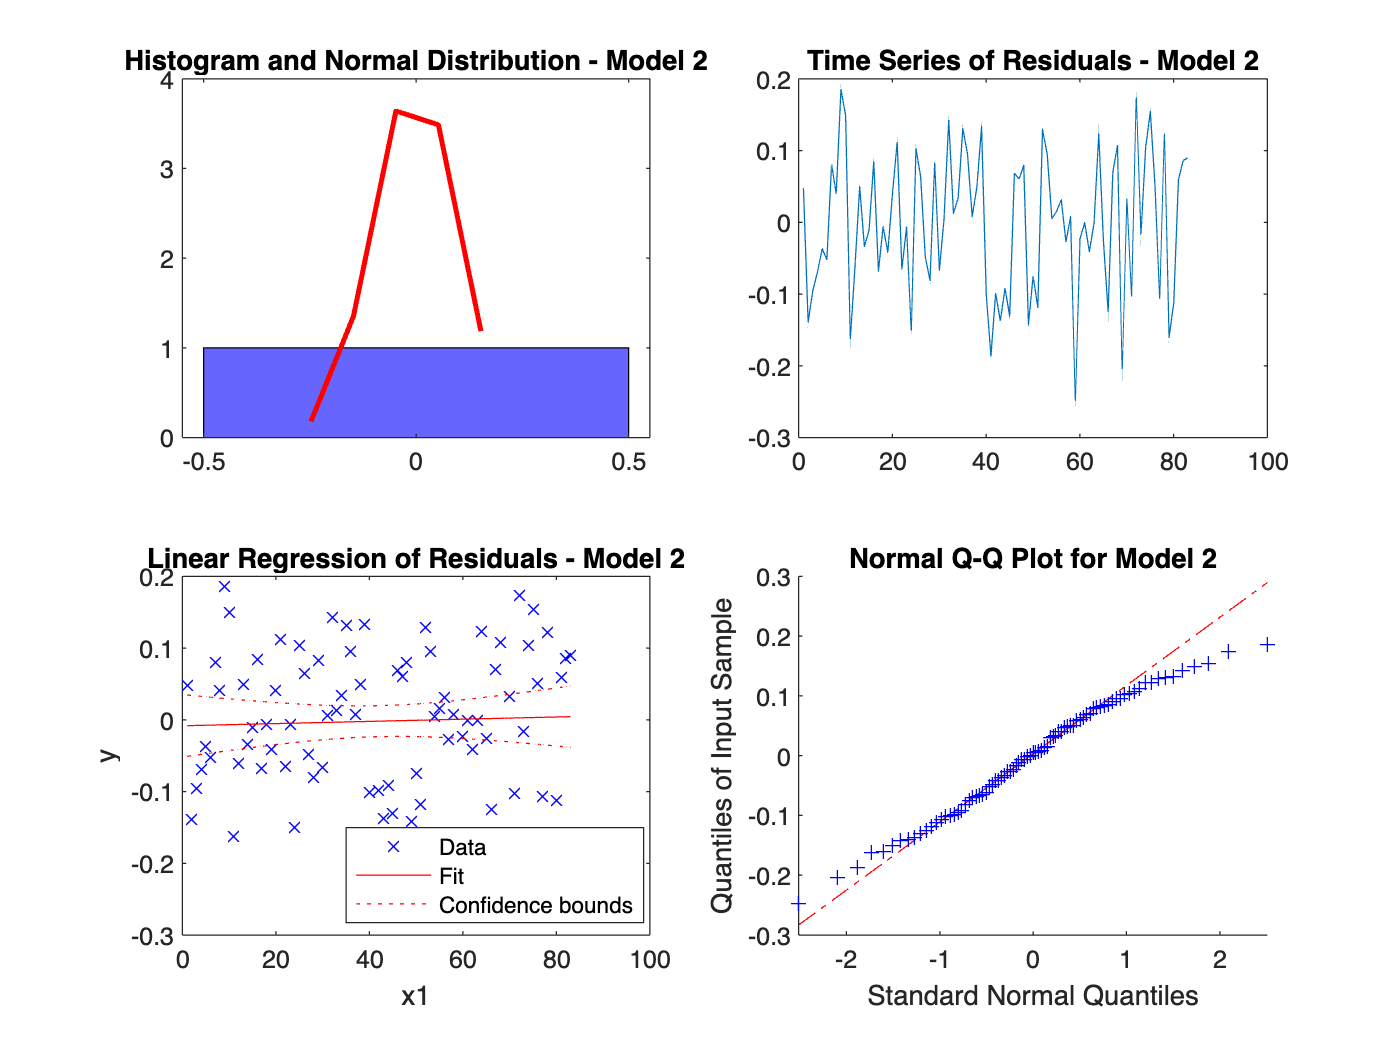

Model_2 = models{2};

% Calculate residuals for Model 2
res2 = infer(Model_2, train_diff1);

% Create a figure with subplots
figure();

% Histogram and Normal distribution curve
subplot(2, 2, 1);
histogram(res2, 'Normalization', 'pdf', 'BinMethod', 'integers', 'FaceColor', 'blue');
hold on;
m = mean(res2);
std_dev = std(res2);
x = min(res2):0.1:max(res2);
y = normpdf(x, m, std_dev);
plot(x, y, 'r', 'LineWidth', 2);
title('Histogram and Normal Distribution - Model 2');

% Plot time series of residuals
subplot(2, 2, 2);
plot(res2);
title('Time Series of Residuals - Model 2');

% Linear regression of residuals
subplot(2, 2, 3);
fitt2 = fitlm((1:length(res2))', res2);
plot(fitt2);
title('Linear Regression of Residuals - Model 2');

% QQ plot of residuals
subplot(2, 2, 4);
qqplot(res2);
title('Normal Q-Q Plot for Model 2');

From the above plots, the histogram and Q-Q plot display normality. However, once again the plot of residuals shows that the trend line slightly strays from the  mean line towards the end. 

Now, we can run diagnostic checks to check the results.


% Open a file for writing normality results to
fileID = fopen('/Users/nkalluri/Desktop/EARTH 175 Final/output/Model2NormalityResults.txt', 'w');

% Perform Shapiro-Wilk test for normality
[~, p_lillie] = lillietest(res2);


% Perform Ljung-Box test
[~, p_lb] = lbqtest(res2, 'Lags', 12);

% Display and write normality test p-values
result_text = ['Shapiro-Wilk test p-value: ', num2str(p_lillie), '\n', ...
               'Ljung-Box test p-value: ', num2str(p_lb), '\n\n'];
disp(result_text);

Shapiro-Wilk test p-value: 0.5\nLjung-Box test p-value: 0.74896\n\n


fprintf(fileID, result_text);

% Fit autoregressive model 
ar_model2 = ar(res2, 5);
ar_coeffs2 = ar_model2.a;

% Display and write AR coefficients to file
fprintf('AR Model Coefficients:\n');

AR Model Coefficients:


fprintf(fileID, 'AR Model Coefficients:\n');
for i = 1:numel(ar_coeffs2)
    fprintf('%d: %.4f\n', i, ar_coeffs2(i));
    fprintf(fileID, '%d: %.4f\n', i, ar_coeffs2(i));
end

1: 1.0000
2: -0.0452
3: 0.0414
4: 0.0104
5: 0.0113
6: 0.2550



fclose(fileID);


From the normality tests in the correpsonding outputted files. Both models pass diagnostic checking as both have p-values well above 0.05. However, Model 2 has slightly higher p-values which is in line with the results from the AIC values in which Model 2 also performed better with a lower AIC of -138.500357 compared to Model 1's AIC of -131.932127.

From these results, we can continue by choosing Model 2 to begin the process of forecasting the data.

# Final Model

The final chosen model is:


$$$Y_t - Y_{t-1} = Z_t - 0.0452*Z_{t-1} + 0.0414*Z_{t-2} + 0.0104*Z_{t-3}$$$


fileID = fopen('/Users/nkalluri/Desktop/EARTH 175 Final/output/model_results.txt', 'w');

model_string = 'Y_t - Y_{t-1} = Z_t - 0.0452*Z_{t-1} + 0.0414*Z_{t-2} + 0.0104*Z_{t-3}';

% Write SARIMA model information
fprintf(fileID, 'Final Chosen Model:\n');
fprintf(fileID, '\nModel 2: \n');
fprintf(fileID, 'ARIMA(1, 1, 3) Model:\n%s\n', model_string);

fclose(fileID);

# Forecasting Observations

Now that we have the final model that will be used, we can begin the process of forecasting for the rest of the testing observations.

% Fit the SARIMA model on the original climate data.
fit_1 = f.fit_sarima_model(train.data, 1, 1, 3);

 
    ARIMA(1,1,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant     0.012115      0.0071543        1.6934        0.090375
    AR{1}        -0.89802        0.09017       -9.9592      2.2988e-23
    MA{1}         0.61374        0.13621        4.5058      6.6115e-06
    MA{2}        -0.52399        0.12133       -4.3187      1.5694e-05
    MA{3}         -0.4157        0.12399       -3.3527      0.00080032
    Variance    0.0088239      0.0016751        5.2678      1.3808e-07

AIC of the fitted model: -146.9624


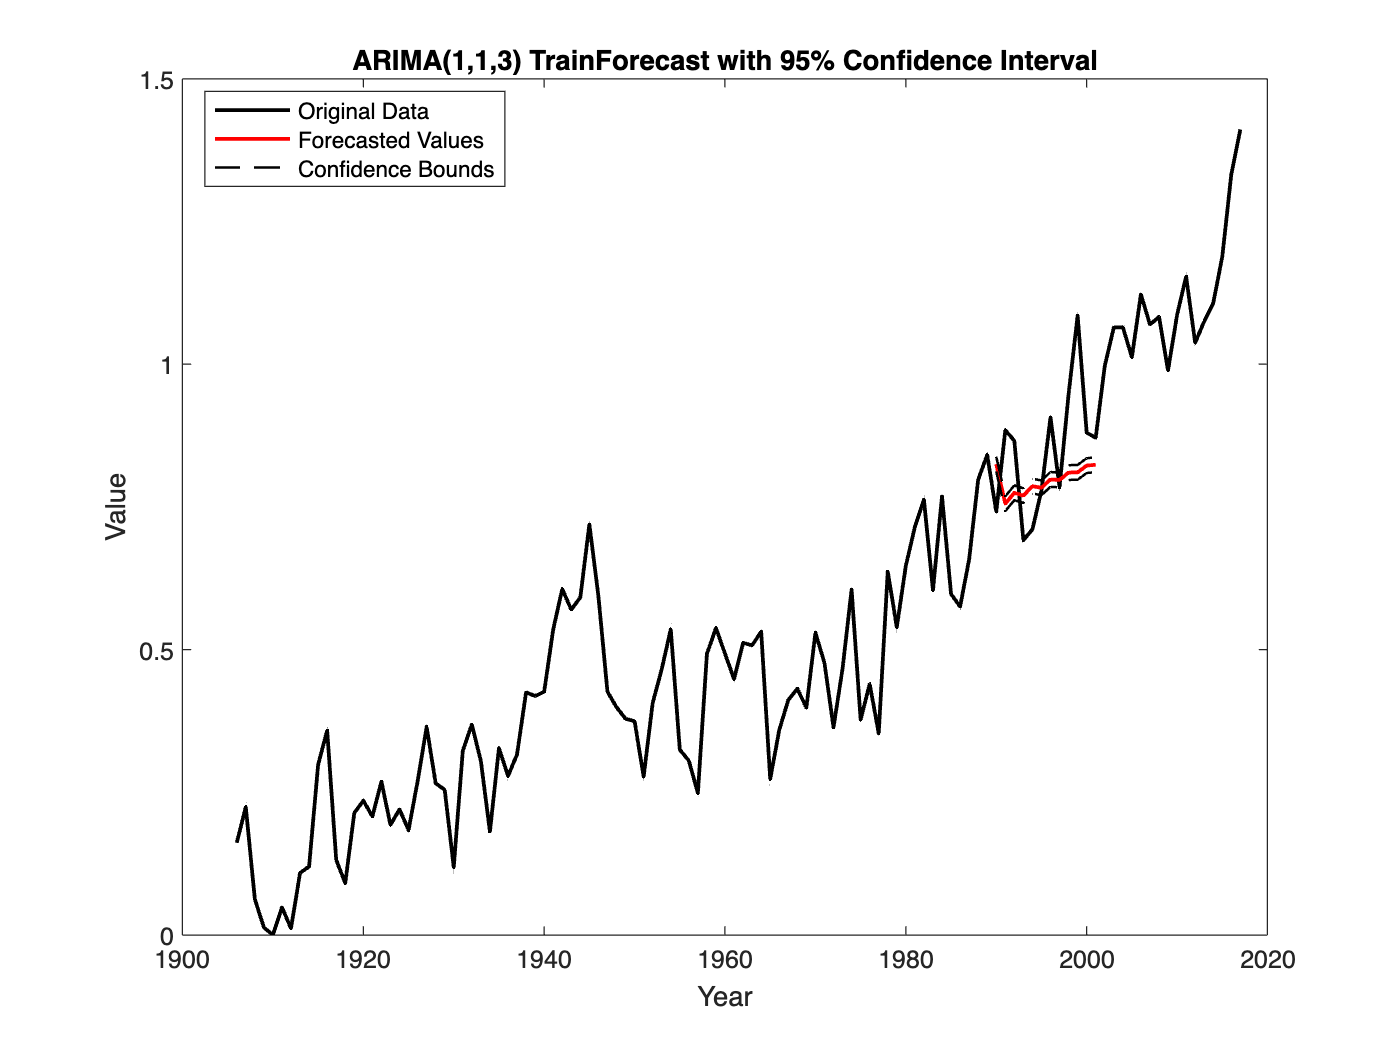

% Forecast 12 values
forecast_values = forecast(fit_1, 12, 'Y0', train.data);

se= std(forecast_values) / sqrt(length(forecast_values));

% Calculate upper and lower confidence bounds
UpperBound = forecast_values + 1.96 * se; % 95% confidence interval
LowerBound = forecast_values - 1.96 * se; % 95% confidence interval

% Plot the climate data starting at year 1905
years = 1905 + (1:length(climate.data));

figure;
plot(years, climate.data, 'k-', 'LineWidth', 1.5);
hold on;
xlabel('Year');
ylabel('Value');
title('ARIMA(1,1,3) TrainForecast with 95% Confidence Interval');

% Plot the forecasted values along with the confidence interval
future_years = 1905 + length(train.data) + (1:12);
plot(future_years, forecast_values, 'r-', 'LineWidth', 1.5);
plot(future_years, UpperBound, 'k--', 'LineWidth', 1);
plot(future_years, LowerBound, 'k--', 'LineWidth', 1);
legend('Original Data', 'Forecasted Values', 'Confidence Bounds');
legend("Position", [0.14627,0.82313,0.21429,0.090476])

hold off;

filename = [plots_folder, 'forecasted__test_values.jpg'];
saveas(gcf, filename);

Based on the above plot, we can see that the observations indicated in red follow the general trend for the data rather than fitting exactly to the variability. We can then use this to predict future observations beyond the dataset.

# Forecasting Future Observations

Now that we have the final model that will be used, we can begin the process of forecasting.

% Fit the SARIMA model on the original climate data.
fit_A = f.fit_sarima_model(climate.data, 1, 1, 3);

 
    ARIMA(1,1,3) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant     0.018118      0.0066449        2.7265       0.0064008
    AR{1}         -0.9372       0.062124       -15.086      2.0069e-51
    MA{1}         0.62189        0.11099        5.6031      2.1055e-08
    MA{2}        -0.55776        0.10039        -5.556      2.7598e-08
    MA{3}         -0.3344       0.098782       -3.3852       0.0007113
    Variance    0.0090126      0.0014782         6.097      1.0806e-09

AIC of the fitted model: -197.5808


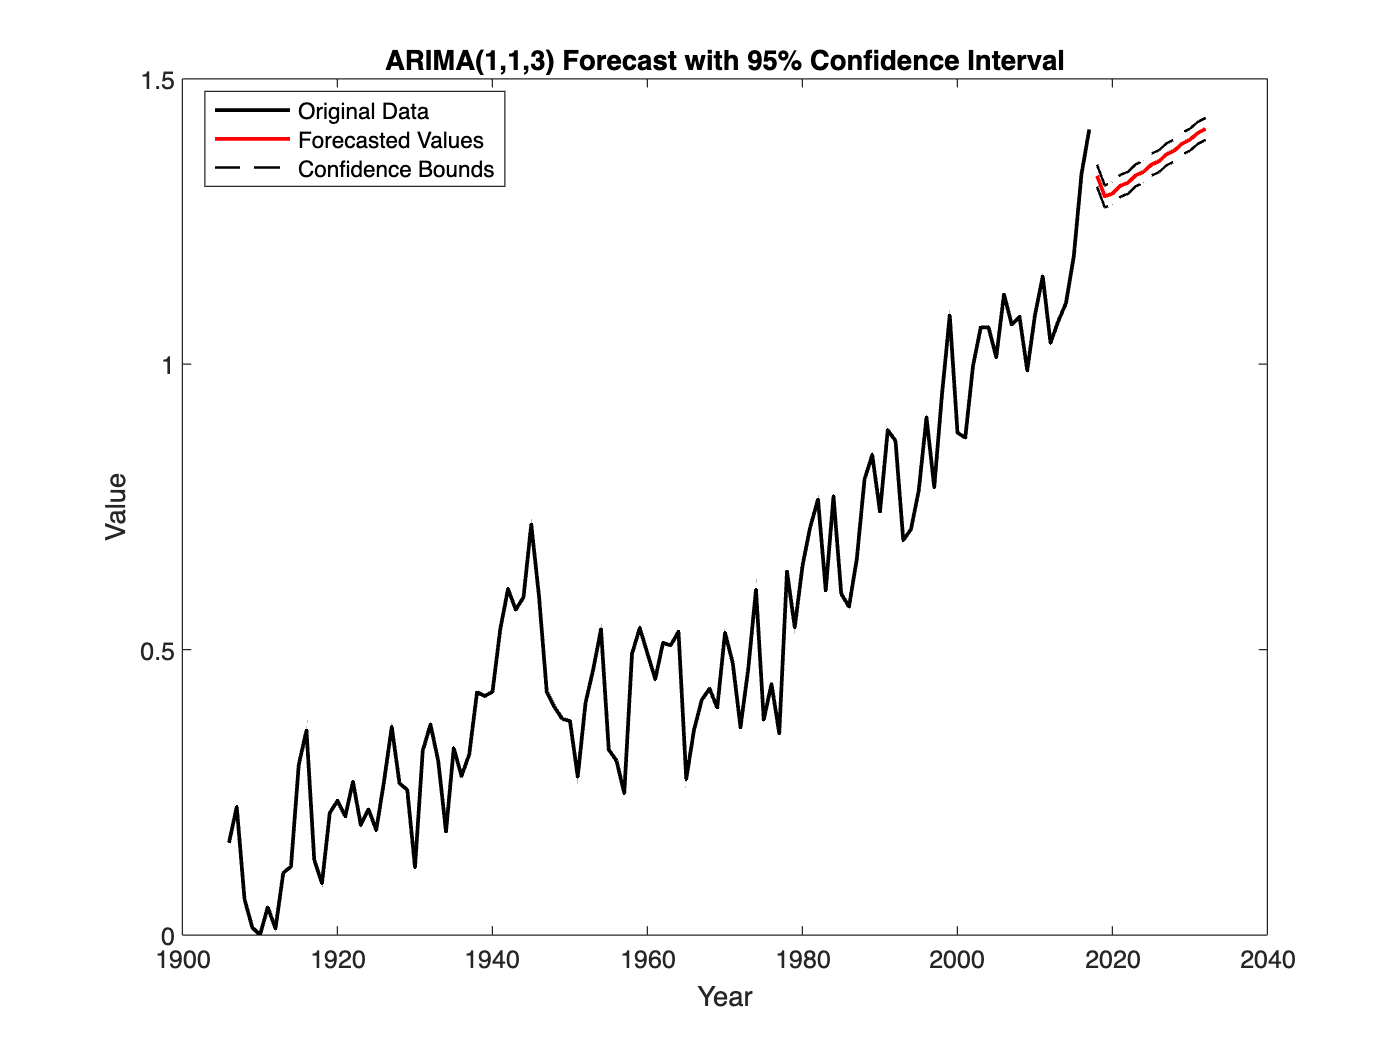


% Forecast 15 values
forecast_values = forecast(fit_A, 15, 'Y0', climate.data);

se= std(forecast_values) / sqrt(length(forecast_values));

% Calculate upper and lower confidence bounds
UpperBound = forecast_values + 1.96 * se; % 95% confidence interval
LowerBound = forecast_values - 1.96 * se; % 95% confidence interval

% Plot the climate data starting at year 1905
years = 1905 + (1:length(climate.data));

figure;
plot(years, climate.data, 'k-', 'LineWidth', 1.5);
hold on;
xlabel('Year');
ylabel('Value');
title('ARIMA(1,1,3) Forecast with 95% Confidence Interval');
% Plot the forecasted values along with the confidence interval

future_years = 1905 + length(climate.data) + (1:15);
plot(future_years, forecast_values, 'r-', 'LineWidth', 1.5);
plot(future_years, UpperBound, 'k--', 'LineWidth', 1);
plot(future_years, LowerBound, 'k--', 'LineWidth', 1);
legend('Original Data', 'Forecasted Values', 'Confidence Bounds');
legend("Position", [0.14627,0.82313,0.21429,0.090476])

hold off;

filename = [plots_folder, 'forecasted_values.jpg'];
saveas(gcf, filename);

# Conclusion

From the resulting plot of forecasted predictions for the next 15 years (2017 to 2031), the forecasts show a significant drop in the mean global variation from 2016 to 2017, from 1.41 to about 1.3, in line with the variation of the data. However, after this, there is a continued, nearly linear increase in the forecasted predictions of the data. This might be attributed to the relatively small sample size of the data (1905 to 2016), causing the model to underfit the data and resulting in simply a general linear trend with some variability. However, the overall trend seems to be accurate as it depicts an upward trend that is in line with the previous data. In the future, fitting a nonlinear time series model such as Markov Switching, Threshold Autoregression, and Smooth Transition Autoregression models might prove to be more accurate, as they do not require fitting nonlinear data into a linear model and will allow the use of a larger subset of data, increasing the sample size, and therefore the predictive accuracy.